# Time-periodic solution for the NLS equation on a dumbbell graph

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

tag='dumbbell';
nX = 32;
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',nX);

## Initial Condition

The first step for our time evolution is developing a good initial condition. We will use a solution to the stationary problem.

First, we must generate solutions to the stationary problem.

nToPlot=4;
nDoubles=1;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

Saved to directory data\dumbbell\022.
Run number is 22.



options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\022\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\022\branch002.
No branching bifurcations found.


Now load the excited state to find the perturbative terms for the soliton.

u = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));
mVec = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'LambdaVec'));
mu = mVec(10);

Find the perturbative terms and create intial conditions.

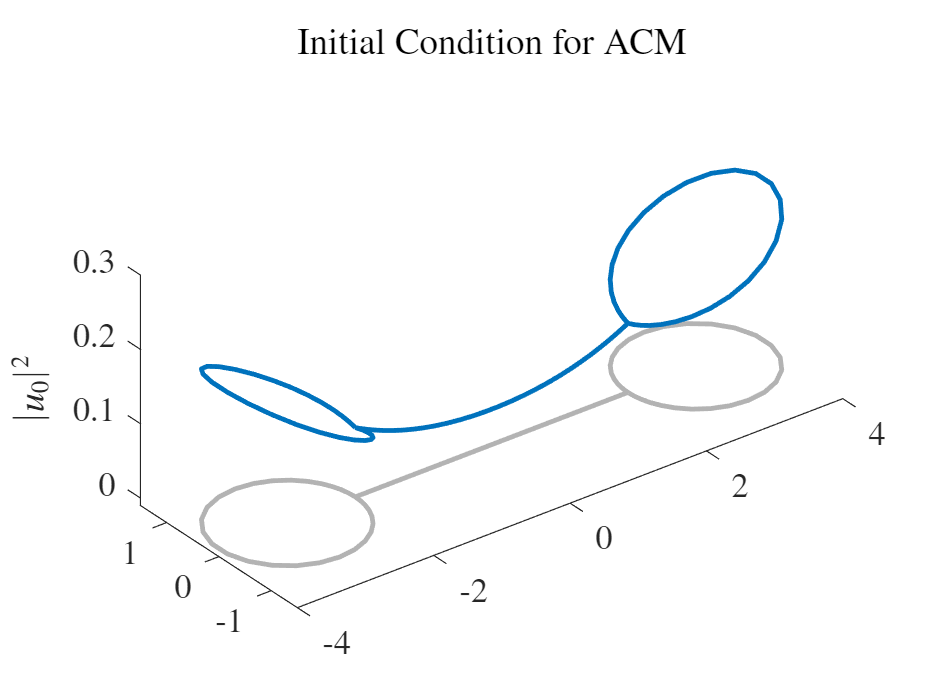

funcs = getGraphFcns(Phi);          % Defining our JL operator
JL = funcs.H(u,mu);
[V,lambda] = eigsJL(Phi,JL,12);     % Finds eigenvalues for JL
f1 = V(1:3*(nX+2),2);
f2 = V((3*(nX+2)+1):end,2);
alpha = 0.01;

u0 = u + alpha*(f1 + conj(f2));           % Note this is also v0!
Phi.plot(abs(u0).^2)
title('Initial Condition for ACM')
zlabel('$|u_0|^2$')
axis([-4 4 -1.5 1.5 -.01 .3])
daspect([1 1 0.1])

## Period

This gives the initial guess for the period.

tend = abs(2*pi/lambda(2));

## Time Periodic Solution

In addition to the initial condition, we need the step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used a modified version of the DoPri-8 scheme.

[t,u,period] = adjointContinuationMethodShift(Phi,u0,tend,mu+alpha^2); % Plus or minus


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the 

Error using daeic12 (line 167)
Need a better guess y0 for consistent initial conditions.

Error in ode15s (line 304)
    [y,yp,f0,dfdy,nFE,nPD,Jfac] = daeic12(odeFcn,odeArgs,t,ICtype,Mt,y,yp0,f0,...

Error in 

save 'ACMsolnCourse.mat' t u;

Shift solution back.

mVec = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn4)],'LambdaVec'));
mu = mVec(32);
v=u;
shift=exp(1i*mu*t);
for i = 1:length(t)
    u(:,i) = shift(i).*v(:,i);
end
% A = Phi.laplacianMatrix;
% B = Phi.weightMatrix;
% f =@(t,z) -1i*(A*z + B*(2*z.^2.*conj(z)));
% [t,u] = Phi.timeEvolve15s(f,u(:,1),t(end));

## Plotting the solution

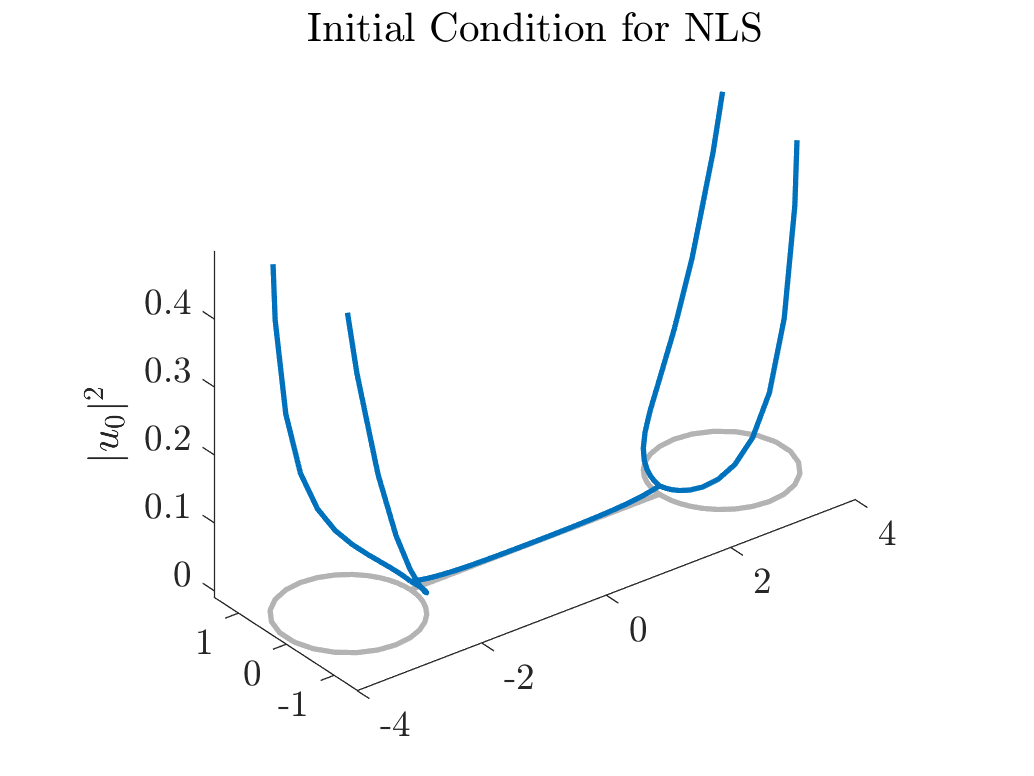

Phi.plot(abs(u(:,1)).^2)
title('Initial Condition for NLS')
zlabel('$|u_0|^2$')
axis([-4 4 -1.5 1.5 -.01 .5])
daspect([1 1 .1])

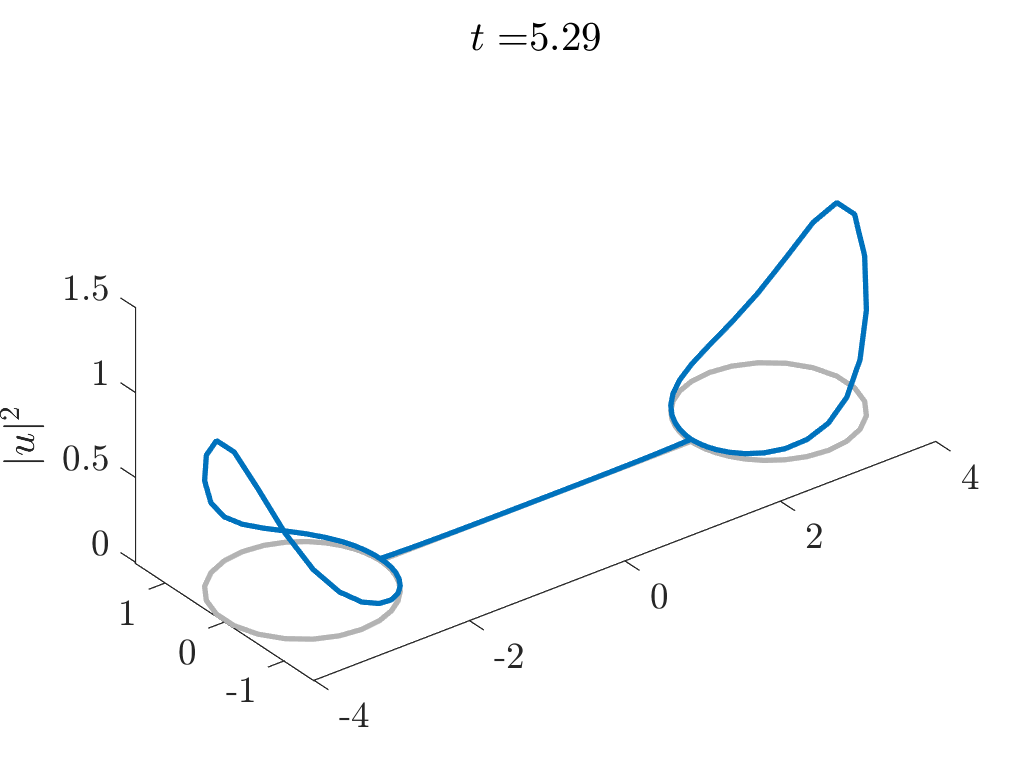

n = size(u,2);
scale = 10;
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-4 4 -1.5 1.5 -.01 1.5])
    daspect([1 1 .5])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$|u|^2$')
    drawnow
end

## Error analysis

Check for conservation of energy, mass and momentum.

% energyDiff = zeros(floor(n/scale),1);
% massDiff = zeros(floor(n/scale),1);
% tplot = zeros(floor(n/scale),1);
% D = Phi.derivative;
% 
% u0energy = Phi.dot( D*u(:,1) , conj(D*u(:,1)) ) - Phi.dot( u(:,1).^2 , conj(u(:,1)).^2 );
% u0mass = Phi.dot(u(:,1),conj(u(:,1)));
% 
% for i=1:floor(n/scale)
%     ui = u(:,scale*i);
%     uiprime=D*ui;
%     term1 = Phi.dot(uiprime,conj(uiprime));
%     term2 = Phi.dot(ui.^2,conj(ui).^2);
%     E = term1 - term2;
%     
%     energyDiff(i) = abs((E-u0energy)/u0energy);
%     massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
%     tplot(i) = t(scale*i);
% end
% 
% 
% disp('')
% figure
% plot(tplot,energyDiff)
% title('Energy error relative to $u_0$')
% xlabel('Time')
% ylabel('Relative error')
% 
% figure
% plot(tplot,massDiff)
% title('Mass error relative to $u_0$')
% xlabel('Time')
% ylabel('Relative error')